# **Validation-SimpleSupportBeam-CustomerLikelihood**

**This example is on **[Bayesian inversion - Simple beam | Examples | UQLab](https://www.uqlab.com/inversion-simple-beam) with known forward model. This document is a test  to see how Uqlab customerLikelihood works.

## **1 - INITIALIZE UQLAB**

clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
F:\abaqustemp\UQLab_Rel2.0.0\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - PRIOR DISTRIBUTION 

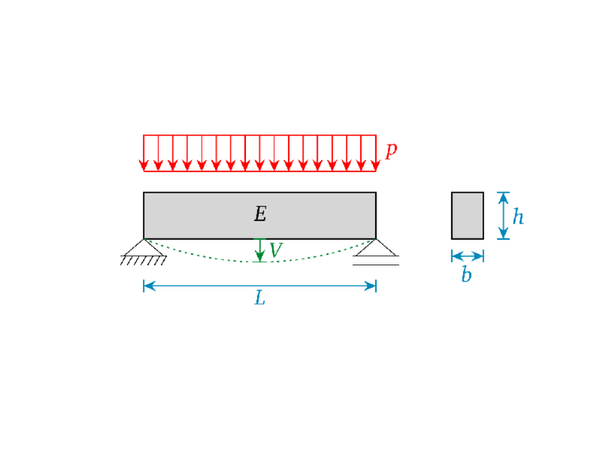

The forward model $V = \frac {5pL^4} {32Ebh^3}$ in inbuilt in the logLikelihood function, b,h,L are constants are not shown in the prior

%Priors on E and p
PriorOpts.Marginals(1).Name = 'E';               % Young's modulus
PriorOpts.Marginals(1).Type = 'LogNormal';
PriorOpts.Marginals(1).Moments = [30 4.5]*1e9;   % (N/m^2)

PriorOpts.Marginals(2).Name = 'p';               % uniform load
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments = [12000 600]; % (N/m)

% Discrepancy parameters
PriorOpts.Marginals(3).Name = 'sigma2'; % variance
PriorOpts.Marginals(3).Type = 'Uniform';
PriorOpts.Marginals(3).Parameters = [0 0.01259^2]; % (m^2) Consistent with given example
myPriorDist = uq_createInput(PriorOpts);

## 3 - Define the custom-loglikelihood 

myLogLikeli = @(params,y) myLOGlikeli(params,y);


## 4 - MEASUREMENT DATA

%Consistent with given example
myData.y = [12.84; 13.12; 12.13; 12.19; 12.67]/1000; % (m)
myData.Name = 'Mid-span deflection';

## 5 - Bayes Analysis

Consistent with example

BayesOpts.Data = myData;
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Type = 'inversion';
BayesAnalysis = uq_createAnalysis(BayesOpts);

The solver was not specified, using MCMC
The sampler was not specified, using affine invariant ensemble sampler
Starting AIES...

|##############################| 100.00%

Finished AIES!


## 6 - Postprocess results

Ground truth should be:

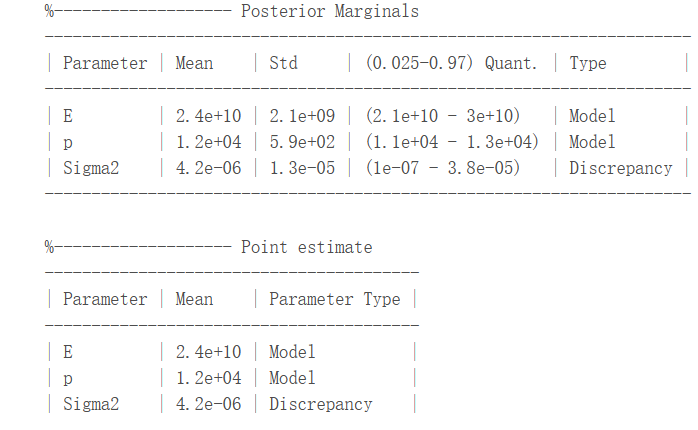

uq_print(BayesAnalysis)


%----------------------- Inversion output -----------------------%
   User-specified likelihood used 
%------------------- Solver
   Solution method:                               MCMC

   Algorithm:                                     AIES
   Duration (HH:MM:SS):                           00:02:12
   Number of sample points:                       3.00e+04

%------------------- Posterior Marginals
---------------------------------------------------------------
| Parameter | Mean    | Std     | (0.025-0.97) Quant. | Type  |
---------------------------------------------------------------
| E         | 2.9e+10 | 4.3e+09 | (2.2e+10 - 3.9e+10) | Model |
| p         | 1.2e+04 | 6e+02   | (1.1e+04 - 1.3e+04) | Model |
| sigma2    | 9.4e-05 | 4.1e-05 | (1.5e-05 - 0.00015) | Model |
---------------------------------------------------------------

%------------------- Point estimate
----------------------------------------
| Parameter | Mean    | Parameter Type |
-------------------------------

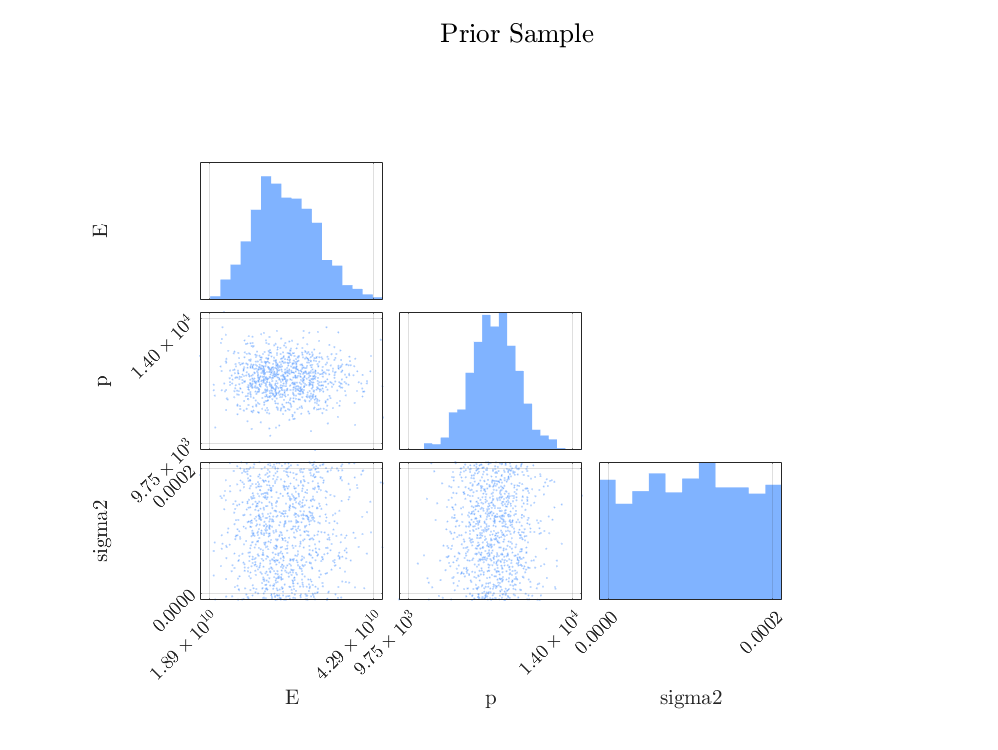

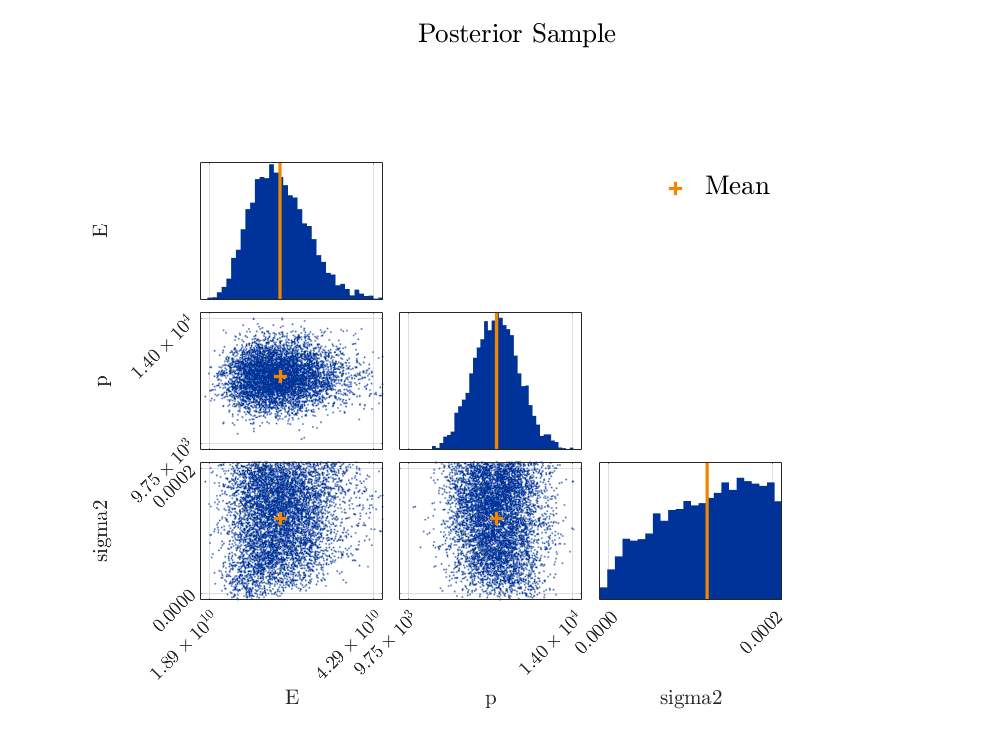

uq_display(BayesAnalysis);